## 总论

余晖的方法，好像之前是想复杂了。但过于简化的模型能够复现出实验结果，恰恰是抓住了问题的本质。

余晖的方法单纯认为离焦图案来自焦面处的光场的继续传播。

## 确定共振角

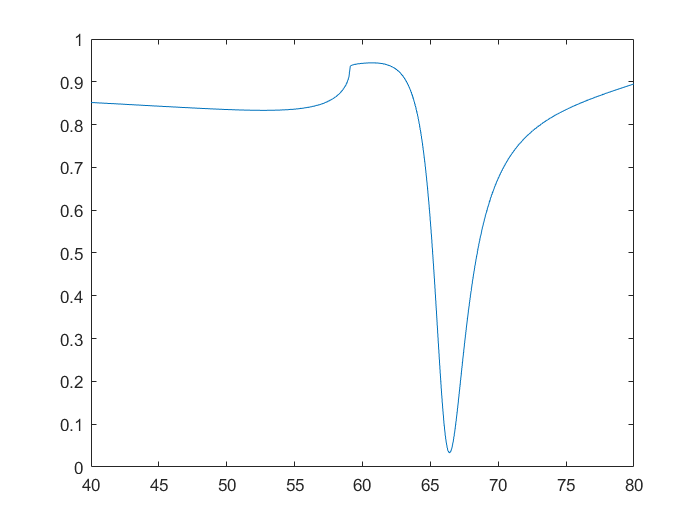

lambda = 670;
n = [1.55,0.13767 + 3.7917i,1.33];
d = [1e9,47,1e9];
theta = 40:.1:80;
N = length(theta);
R = zeros(1,N);
for ii = 1:N
    [R(ii),~] = TMM('p',lambda,theta(ii),d,n);  
end
figure
plot(theta,abs(R).^2)

## 条件初始化

theta_res = 66.4*pi/180;
alpha = 1;    % 散射系数
lambda = lambda*1e-9;
epsilon_au = -14.358 + 1.0440i;
epsilon_water = 1.33^2;
c = 3e8;
omega = 2*pi*c/lambda;
k0 = 1.33*2*pi/lambda;   % 真空自由波矢
kx = imag(sqrt(epsilon_water*epsilon_au/(epsilon_au + epsilon_water)*omega^2/c^2)); % spp横向传播波矢虚部
kspp = real(sqrt(epsilon_water*epsilon_au/(epsilon_au + epsilon_water)*omega^2/c^2));   % spp横向波矢实部
1/kx

ans = 1.4791e-05

kx = sqrt(real(epsilon_au)*epsilon_water/(real(epsilon_au)+epsilon_water)) ...
    * imag(epsilon_au)*epsilon_water/(real(epsilon_au)+epsilon_water)/2/real(epsilon_au) ...
    *2*pi/lambda

kx = 6.8044e+04

1/kx/2

ans = 7.3482e-06

## 生成平面波和散射波

x = -500:500;
delta_sampling = 10^(-7.5);  % 空间采样间隔
[X,Y] = meshgrid(x,x);
Ei = exp(i*kspp*X*delta_sampling);
R = sqrt(X.^2 + Y.^2);
Rho = R*delta_sampling;
psi_ = 0.3*pi;
% f = figure;
% set(f,'visible','off');
Value = zeros([size(X),101]);
Es = alpha*exp(-kx*Rho).*exp(i*(kspp*Rho + psi_));   % 焦面处散射波
Fs = fftshift(fft2(ifftshift(Es))); % 焦面处水平面频谱

z = 5*1e-6;  % 离焦距离
kz = sqrt((1.55*k0)^2 - (2*pi/delta_sampling./length(x)*R).^2);
Fsz = Fs.*exp(i*kz*z);
Fsz(imag(kz)~=0) = 0;
Usz = fftshift(ifft2(ifftshift(Fsz)));
Uz = Usz + Ei;
imagesc(abs(Usz).^2)
colormap(gray)
%     caxis([0.998 1.008])
title(['z = ' num2str(z*1e6) 'um'],'fontsize',15,'FontWeight','bold');
axis off
axis square

% for ii = -50:50
%     z = ii*0.1e-6;  % 离焦距离
%     kz = sqrt((1.55*k0)^2 - (2*pi/delta_sampling./length(x)*R).^2);
%     Fsz = Fs.*exp(i*kz*z);
%     Fsz(imag(kz)~=0) = 0;
%     Usz = fftshift(ifft2(ifftshift(Fsz)));
%     Uz = Usz + Ei;
%     imagesc(abs(Uz))
%     colormap(gray)
% %     caxis([0.998 1.008])
%     title(['z = ' num2str(ii*100) 'nm'],'fontsize',15,'FontWeight','bold');
%     axis off
%     axis square
%     pause(0.5)
%     Value(:,:,ii+51) = Usz;
% end

## 制作视频

% myVideo = VideoWriter('myVideo.avi'); 

## 保存数据

% savepath = 'D:\work\SPRM理论研究\离焦\theta_66.4_-5um_100nm_5um.mat';
% save(savepath,'Value','-v7.3')
% 
% videopath = 'D:\work\SPRM理论研究\离焦\theta_66.4_-5um_100nm_5um.avi';
% myVideo = VideoWriter(videopath);
% myVideo.FrameRate = 10;
% open(myVideo);
% writeVideo(myVideo,reshape(temp,[1001,1001,1,101]));
% close(myVideo)